# Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizi una cifra di merito.

Si possono scegliere tanti vincoli e cifre di merito, ma la struttura base rimane simile.

In quest'esempio il controllore è un PID con filtro sull'azione derivativa


$$C(s)=PID(s)=K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_fs+1}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato carico

clear all;close all;clc;
Jm=2e-2;
Jc=10e-2;
k=1000;
h=0.3;
hm=.001;
model=ElasticSystemModel(Jm,Jc,k,h,hm);
sys_vel_carico=model(4,1);

La cifra di merito è


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


(alternativa $J=-\omega_c$ massimizzare la pulsazione di taglio)

con $\omega_c$ la frequenza (pulsazione) di taglio, e $\omega_{c,des}$ il valore desiderato.

Le incognite del problema sono $x=[K_p,\;K_i,\;K_d,\;T_f]$

wc_des=10;
J=@(x)pidvel_cost_function(x,sys_vel_carico,wc_des);

I vincoli sono (potete modificarli, aggiungerne, toglierne)

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

MS=1.4;
wh=50;
Fh_max=0.1;
wl=0.01;
Dh_max=0.1;
PM_min=60;

w_vector=logspace(-3,3)'; % [10^-3,10^3]
w_vector=sort([w_vector;wl;wh]);

nlcon=@(x)pidvel_constraints(x,sys_vel_carico,w_vector,MS,wh,Fh_max,wl,Dh_max,PM_min);

Risolvo il problema con GlobalSearch, la soluzione è *globale*.

Impongo che $K_p\in[0.01,100]$,$K_i\in[0.01,100]$,$K_d\in[0.0,100]$,$T_f\in[0.01,100]$


gs = GlobalSearch('Display','iter');
x0=[1,1,0,10];

problem = createOptimProblem('fmincon','x0',x0,...
    'objective',J,'lb',[0.01,0.01,0,0.01],'ub',[100,100,100,100],'nonlcon',nlcon);
x = run(gs,problem)


 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0      282       65.76                                   65.76            2    Initial Point
     200     1724       65.76                                   65.76            2    Stage 1 Local
     300     1827       65.76     1.604e+05        137.4                              Stage 2 Search
     400     1927       65.76     1.993e+05        343.5                              Stage 2 Search
     446     2254       65.76         189.3          495        65.76            1    Stage 2 Local
     500     2308       65.76     1.646e+05          273                              Stage 2 Search
     600     2408       65.76     3.167e+06        680.9                              Stage 2 Search
     700     2508       65.76     3.167e+06         1696                              Stage 2 S

x =     0.1960    0.2161    0.0000    5.1285


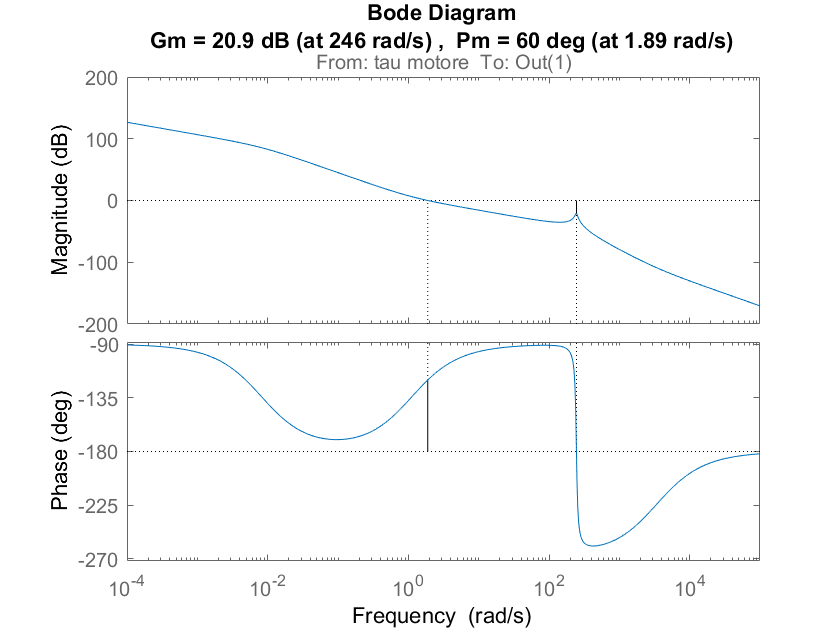

Kp=x(1);
Ki=x(2);
Kd=x(3);
Tf=x(4);
s=tf('s');
C=Kp+Ki/s+Kd*s/(Tf*s+1);

figure(1)
margin(C*sys_vel_carico)

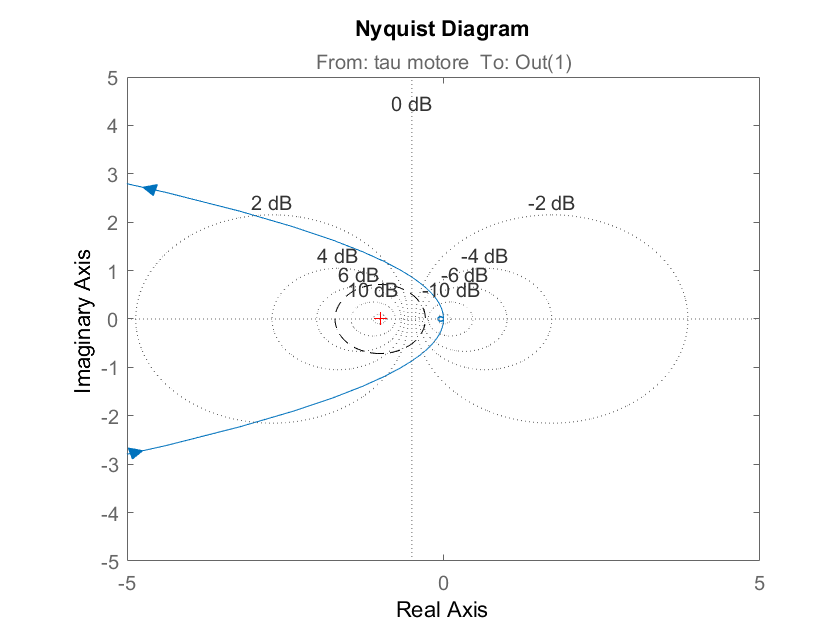

figure(2)
%MS=max(S)=max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(C*sys_vel_carico)
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/MS*sin(angolo),1/MS*cos(angolo),'--k')
hold off
xlim([-5 5])
ylim([-5 5])